%% 6번 문제
clear; clc;

rng('default');

% (a) 
num_paths = 5000;
num_days = 60;
returns = 0.0008 + 0.015 * randn(num_paths, num_days);

% (b)
asset_paths = zeros(num_paths, num_days + 1);
asset_paths(:, 1) = 100; % 0일차(초기 자산)

for i = 1:num_days
    asset_paths(:, i+1) = asset_paths(:, i) .* (1 + returns(:, i));
end

% (c) 
final_assets = asset_paths(:, end);
mean_final = mean(final_assets);
min_final = min(final_assets);
max_final = max(final_assets);

fprintf('=== 6번 결과 ===\n');

=== 6번 결과 ===


fprintf('마지막 날 자산가치 평균: %.2f\n', mean_final);

마지막 날 자산가치 평균: 104.89


fprintf('마지막 날 자산가치 최솟값: %.2f\n', min_final);

마지막 날 자산가치 최솟값: 67.27


fprintf('마지막 날 자산가치 최댓값: %.2f\n', max_final);

마지막 날 자산가치 최댓값: 157.74



% (d) 
prob_less_than_100 = mean(final_assets < 100);
fprintf('마지막 날 자산가치가 원금(100)보다 작을 확률: %.2f%%\n', prob_less_than_100 * 100);

마지막 날 자산가치가 원금(100)보다 작을 확률: 35.32%


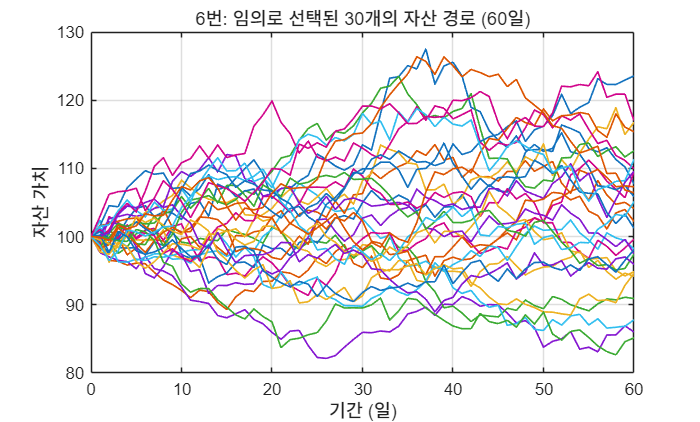


% (e) 
selected_indices = randperm(num_paths, 30);

figure(7);
plot(0:num_days, asset_paths(selected_indices, :)', 'LineWidth', 1);
title('6번: 임의로 선택된 30개의 자산 경로 (60일)');
xlabel('기간 (일)');
ylabel('자산 가치');
grid on;